# クーロンカウント法による SOC 予測

Copyright 2021 Michio Inoue

初期 SOC の値が既知であれば電流値を積算することで SOC がある程度予測できるはず、ということで実施してみる。テストケースでは確認できないが、実際学習データでは SOC の初期値は 100% であるケースばかりなので有効かもしれない。

電流（Current）で各時間ステップ（dt）を掛けて累積和をとったものをを Ah とする。SOC は以下の式で求まる。

SOC = (2.9 - Ah)/2.9 x 100

## 学習データにおける SOC 計算精度確認

clear
traindata = load('traindata.mat');

fields = fieldnames(traindata)

fields = 15×1 の cell 配列
    {'n10degCCycle'}
    {'n10degCNN'   }
    {'n10degCUS06' }
    {'n20degCCycle'}
    {'n20degCNN'   }
    {'n20degCUS06' }
    {'p0degCCycle' }
    {'p0degCNN'    }
    {'p0degCUS06'  }
    {'p10degCCycle'}
    {'p10degCNN'   }
    {'p10degCUS06' }
    {'p25degCCycle'}
    {'p25degCNN'   }
    {'p25degCUS06' }


各データごとにクーランカウント法で SOC 算出する

for ii=1:length(fields)
    % 学習データ
    data = traindata.(fields{ii});

    dAh = data.Current.*[0; diff(data.Time)]/3600; % Ah
    Ah = cumsum(dAh);
    SOC = (2.9+Ah)/2.9*100; % Ah -> SOC
    data.predSOC = max(0,min(SOC,100));
    data.difSOC = data.SOC - data.predSOC;

    % RMSE
    rmse = sqrt(mean(data.difSOC.^2));
    disp("RMSE: " + rmse + " (" + fields{ii} + ")")

    % 予測値、誤差の保存
    traindata.(fields{ii}) = data;
end

RMSE: 0.021292 (n10degCCycle)
RMSE: 0.037905 (n10degCNN)
RMSE: 0.031027 (n10degCUS06)
RMSE: 0.030393 (n20degCCycle)
RMSE: 0.02127 (n20degCNN)
RMSE: 0.023894 (n20degCUS06)
RMSE: 0.020637 (p0degCCycle)
RMSE: 0.038911 (p0degCNN)
RMSE: 0.016766 (p0degCUS06)
RMSE: 0.025178 (p10degCCycle)
RMSE: 0.021201 (p10degCNN)
RMSE: 0.023186 (p10degCUS06)
RMSE: 0.030701 (p25degCCycle)
RMSE: 0.019103 (p25degCNN)
RMSE: 0.01347 (p25degCUS06)


悪くない。

## テストデータの SOC 計算

テストデータ読み込み（事前読み込み済み）

load('testdata.mat','testdata');

各温度 x 各ドライブサイクルの組み合わせ（３０通り）が１つずつ結合されたデータである（別途確認ずみ）ので、単純に抜き出して上と同じ処理を繰り返すのみ。

testdata.DriveCycle = string(testdata.DriveCycle);
testID = string(testdata.Chamber_Temp_degC) + testdata.DriveCycle;
uniqueCycles = unique(testID)

uniqueCycles = 30×1 の string 配列
    "-10Cycle_2"
    "-10Cycle_3"
    "-10Cycle_4"
    "-10HWFET"
    "-10LA92"
    "-10UDDS"
    "-20Cycle_2"
    "-20Cycle_3"
    "-20Cycle_4"
    "-20HWFET"
    "-20LA92"
    "-20UDDS"
    "0Cycle_2"
    "0Cycle_3"
    "0Cycle_4"
    "0HWFET"
    "0LA92"
    "0UDDS"
    "10Cycle_2"
    "10Cycle_3"
    "10Cycle_4"
    "10HWFET"
    "10LA92"
    "10UDDS"
    "25Cycle_2"
    "25Cycle_3"
    "25Cycle_4"
    "25HWFET"
    "25LA92"
    "25UDDS"


それぞれの組み合わせ（温度 x ドライブサイクル）に対して処理

for ii = 1:length(uniqueCycles)

    idx = testID == uniqueCycles(ii);
    % 必要なのは Time と Current
    data = testdata(idx,["ID","Time","Current"]);

    dAh = data.Current.*[0; diff(data.Time)]/3600; % Ah
    Ah = cumsum(dAh);
    SOC = (2.9+Ah)/2.9*100; % Ah -> SOC
    SOC = max(0,min(SOC,100));

    % 保存
    testdata.SOC(idx) = SOC;
end


提出用ファイル作成

% writetable(testdata(:,["ID","SOC"]),'SOC_coulombCounting.csv')

## 考察: LB 0.0507

エラーも小さく、物理現象と紐づいた明確な手法で魅力的だがここから更に改善するためにエラーの要因について考えるために、学習データにおけるエラーを各ドライブサイクルごとに分けてプロットしておく。

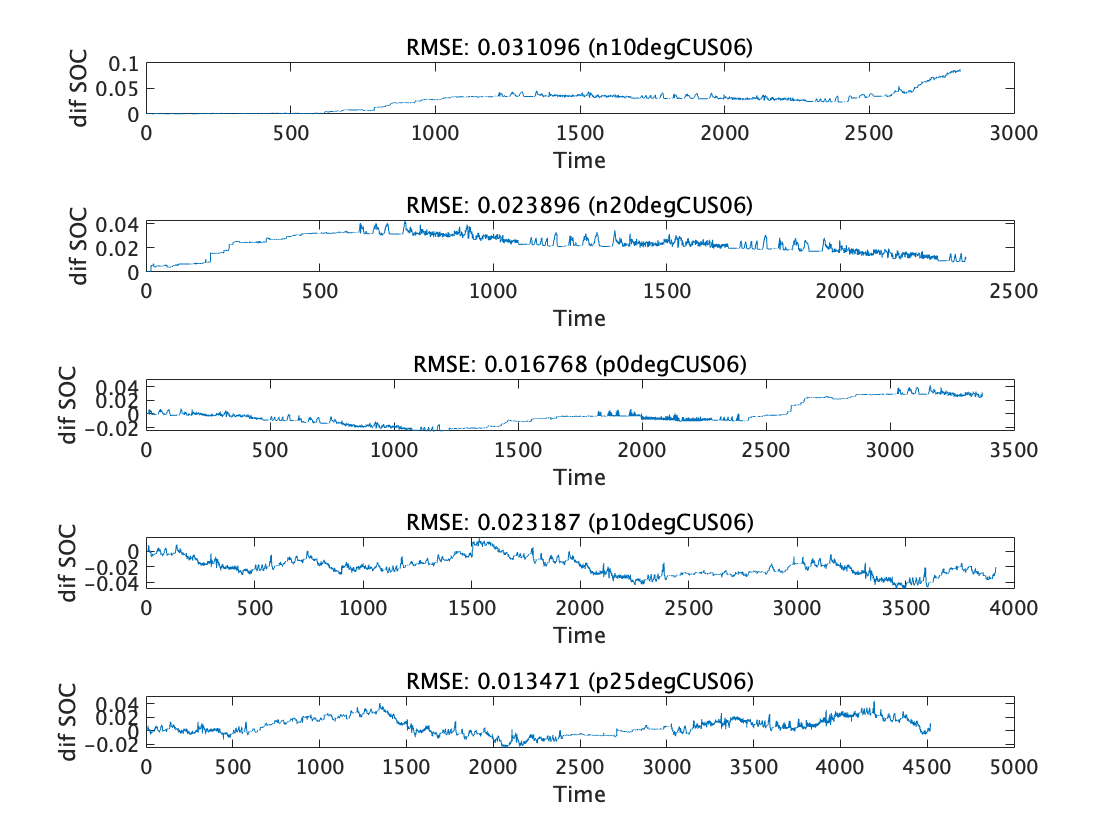

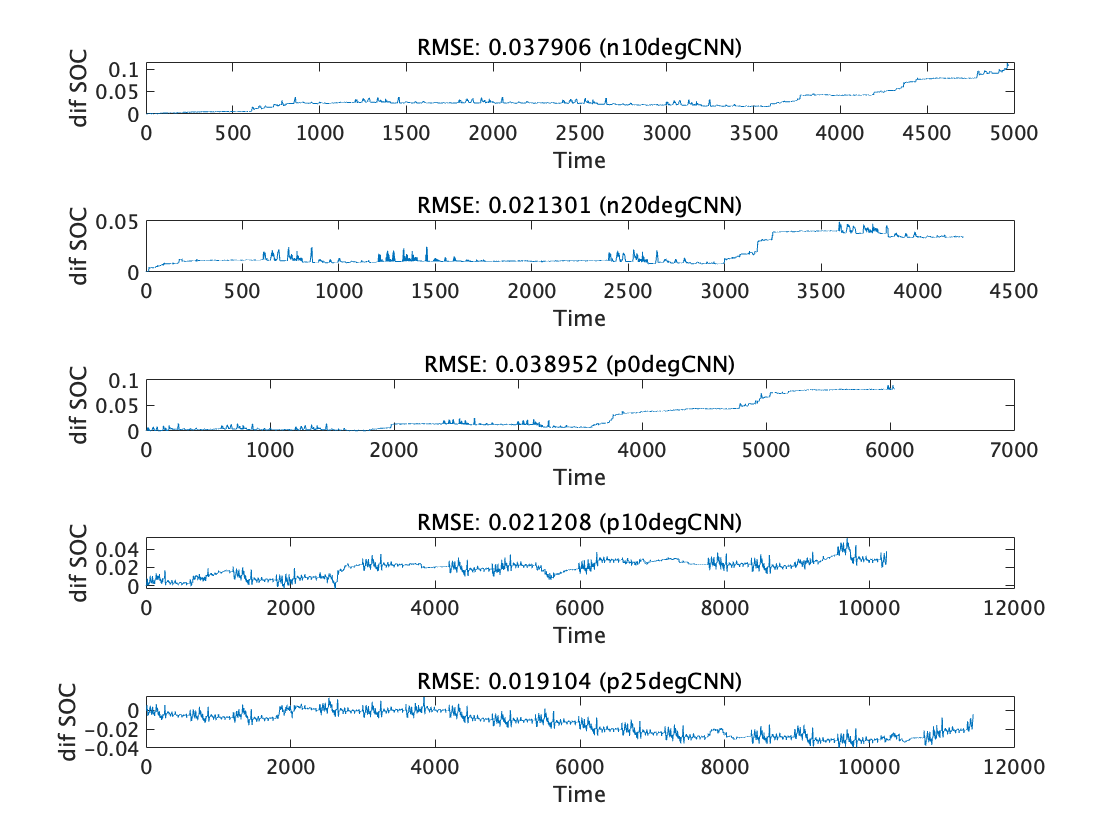

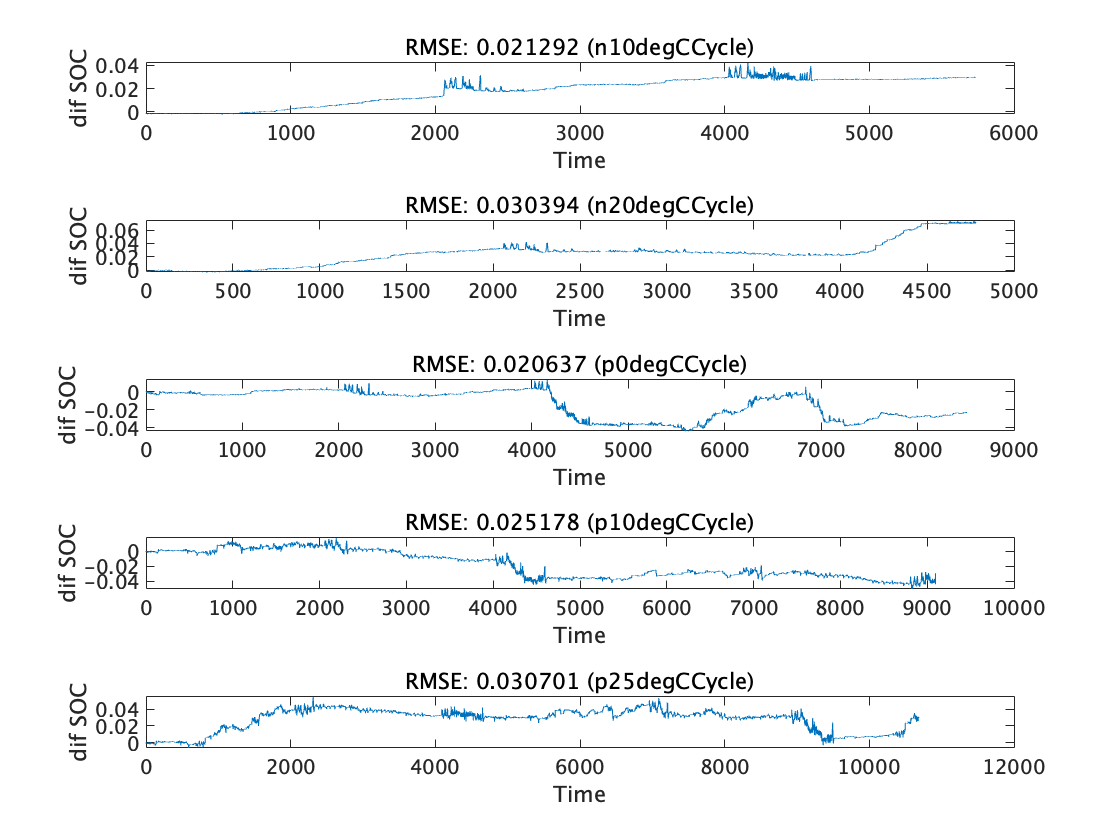

cycles = ["US06","NN","Cycle"];
for jj=1:length(cycles)
    thisCycle = cycles(jj);

    thisFields = fields(contains(fields,thisCycle));

    figure
    tiledlayout(5,1);
    for ii=1:length(thisFields)
        % 学習データ
        data = traindata.(thisFields{ii});

        % 100 から下がったところから開始する
        idx = find(data.SOC<100,1);
        data(1:idx,:) = [];
        data.Time = data.Time - data.Time(1);


        nexttile
        plot(data.Time, data.difSOC);

        rmse = sqrt(mean(data.difSOC.^2));
        title("RMSE: " + rmse + " (" + thisFields{ii} + ")")
        xlabel('Time');
        ylabel('dif SOC')
    end
end

function h = cycle_stackedplot(input)
tmp = input;
tmp.Time = milliseconds(tmp.Time);
tmp = table2timetable(tmp,'RowTimes','Time');
tmp.dT = [0;diff(tmp.Time)];
h = stackedplot(tmp);
end

